%% Question 1
clear all
close all
% rosinit
sub = rossubscriber('/usb_cam/image_raw');
[pub,msg] = rospublisher('/usb_cam/image_raw')

pub =   Publisher with properties:

         TopicName: '/usb_cam/image_raw'
    NumSubscribers: 2
        IsLatching: 1
       MessageType: 'sensor_msgs/Image'
        DataFormat: 'object'


msg =   ROS Image message with properties:

    MessageType: 'sensor_msgs/Image'
         Header: [1×1 Header]
         Height: 0
          Width: 0
       Encoding: ''
    IsBigendian: 0
           Step: 0
           Data: [0×1 uint8]

  Use showdetails to show the contents of the message


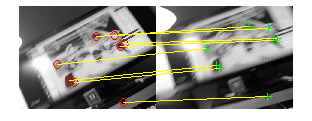


[scanData,~,~] = receive(sub,1000000000);
[scanData2,status,statustext] = receive(sub,100000);

original = rgb2gray (scanData.readImage);
distorted = rgb2gray (scanData2.readImage);

ptsOriginal = detectSURFFeatures(original);
ptsDistorted = detectSURFFeatures(distorted);
[featuresOriginal, validPtsOriginal] = extractFeatures(original,ptsOriginal);
[featuresDistorted, validPtsDistorted] = extractFeatures(distorted,ptsDistorted);

indexPairs = matchFeatures(featuresOriginal,featuresDistorted);
matchedOriginal = validPtsOriginal(indexPairs(:,1));
matchedDistorted = validPtsDistorted(indexPairs(:,2));

figure;
showMatchedFeatures(original,distorted,matchedOriginal,matchedDistorted,'montage');

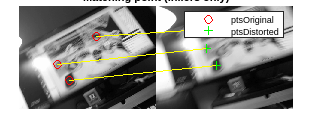


[tform,inlierDistorted,inlierOriginal] = estimateGeometricTransform (matchedDistorted,matchedOriginal,'similarity');

figure;
showMatchedFeatures(original,distorted,inlierOriginal,inlierDistorted,'montage');
title('Matching point (inliers only)');
legend ('ptsOriginal','ptsDistorted');

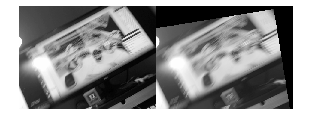


Tinv = tform.invert.T;
ss = Tinv(2,1);
sc = Tinv(1,1);
scaleRecovered = sqrt(ss*ss+sc*sc);
thetaRecovered = atan2(ss,sc)*180/pi;

outputView = imref2d(size(original));
recovered = imwarp(distorted,tform,'OutputView',outputView);
figure;
imshowpair(original,recovered,'montage');

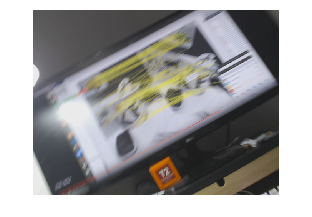


imshow(scanData.readImage);

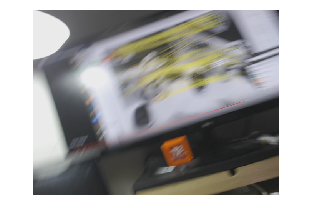

imshow(scanData2.readImage);

% 
% 
% msg = scanData;
% send(pub,msg);
%msg = sub.LatestMessage.Data;
% img = rosReadImage(msg);    
% imshow(msg);
% rosshutdown